MTOW = 158356;
WingLoad = 93.55; 

%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = MTOW*0.946

W = 1.4980e+05

Vmax = 759.5

Vmax = 759.5000


%Airfoil Parameters
Cla = 2*pi*pi/180

Cla = 0.1097

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

ZeroLiftAngle = -3;


%Planform Parameters
S = MTOW/WingLoad %ft^2

S = 1.6927e+03

b = 118;
AR = b^2/S

AR = 8.2257

TaperRatio = 0.4;
Df = 15.5; %ft
Cr = 2*S/(b*(1+TaperRatio))

Cr = 20.4932

Cf = Cr*(1-(1-TaperRatio)*2*Df/2/b)

Cf = 18.8781

SweepQuartC = 0

SweepQuartC = 0

Ne = 0

Ne = 0


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


Sexp = S-(Cf+Cr)/2*Df

Sexp = 1.3876e+03

beta = sqrt(1-M^2)

beta = 0.8134

eta = Cla/(2*pi/beta)

eta = 0.0142


% for i = 1:46
%     
%     SweepQuartC(i) = i-1;
%     
% 
%     
%     SweepMaxT = atand(tand(SweepQuartC(i))-4/AR*((LocMaxT-0.25)*(1-TaperRatio)/(1+TaperRatio)))
%     CLa(i) = (2*pi*AR*Sexp/S)/(2+sqrt(4+(AR^2*beta^2)/(eta^2)*(1+(tand(SweepMaxT)^2)/(beta^2))))
%     
% end
% 
% plot (SweepQuartC,CLa)
% xlabel('Quater Chord Sweep Angle (\circ), {\it \Lambda_{0.25c}}')
% ylabel('Wing Lift Curve Slope, {\it C_{L,\alpha}}')
% grid on

for i = 1:100
    
    TaperRatio(i) = 0.01*i - 0.01
    
    TaperFunc = 0.005*(1+1.5*(TaperRatio(i)-0.6)^2)
    K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)
    
    e(i) = 1/(pi*K*AR)
    
end

TaperRatio = 0

TaperFunc = 0.0077

K = 0.0477

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100


TaperFunc = 0.0076

K = 0.0477

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200


TaperFunc = 0.0075

K = 0.0477

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300


TaperFunc = 0.0074

K = 0.0476

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400


TaperFunc = 0.0074

K = 0.0476

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500


TaperFunc = 0.0073

K = 0.0476

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600


TaperFunc = 0.0072

K = 0.0475

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700


TaperFunc = 0.0071

K = 0.0475

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800


TaperFunc = 0.0070

K = 0.0475

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900


TaperFunc = 0.0070

K = 0.0475

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000


TaperFunc = 0.0069

K = 0.0474

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100


TaperFunc = 0.0068

K = 0.0474

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200


TaperFunc = 0.0067

K = 0.0474

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300


TaperFunc = 0.0067

K = 0.0474

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400


TaperFunc = 0.0066

K = 0.0473

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500


TaperFunc = 0.0065

K = 0.0473

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600


TaperFunc = 0.0065

K = 0.0473

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700


TaperFunc = 0.0064

K = 0.0473

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800


TaperFunc = 0.0063

K = 0.0472

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900


TaperFunc = 0.0063

K = 0.0472

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000


TaperFunc = 0.0062

K = 0.0472

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100


TaperFunc = 0.0061

K = 0.0472

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200


TaperFunc = 0.0061

K = 0.0471

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300


TaperFunc = 0.0060

K = 0.0471

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400


TaperFunc = 0.0060

K = 0.0471

e =     0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231    0.8234    0.8237    0.8240    0.8242    0.8245    0.8247    0.8250    0.8252    0.8254    0.8256    0.8258    0.8260    0.8262    0.8263    0.8265    0.8267    0.8268    0.8269    0.8270    0.8272


TaperRatio =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500


TaperFunc = 0.0059

K = 0.0471

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×27
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600


TaperFunc = 0.0059

K = 0.0471

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×28
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700


TaperFunc = 0.0058

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×29
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800


TaperFunc = 0.0058

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0057

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0057

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0056

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0056

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0055

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0055

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0055

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0054

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0054

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0054

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0053

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0053

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0053

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0052

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0052

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0052

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0052

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0467

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0050

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0051

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0052

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0052

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0052

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0052

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0053

K = 0.0468

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0053

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0053

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0054

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0054

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0054

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0055

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0055

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0055

K = 0.0469

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0056

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0056

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0057

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0057

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0058

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0058

K = 0.0470

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0059

K = 0.0471

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0059

K = 0.0471

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0060

K = 0.0471

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0060

K = 0.0471

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0061

K = 0.0471

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


TaperRatio = 1×30
         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900


TaperFunc = 0.0061

K = 0.0472

e = 1×30
    0.8106    0.8112    0.8117    0.8123    0.8128    0.8133    0.8138    0.8143    0.8148    0.8153    0.8158    0.8162    0.8167    0.8172    0.8176    0.8180    0.8184    0.8189    0.8193    0.8197    0.8200    0.8204    0.8208    0.8211    0.8215    0.8218    0.8222    0.8225    0.8228    0.8231


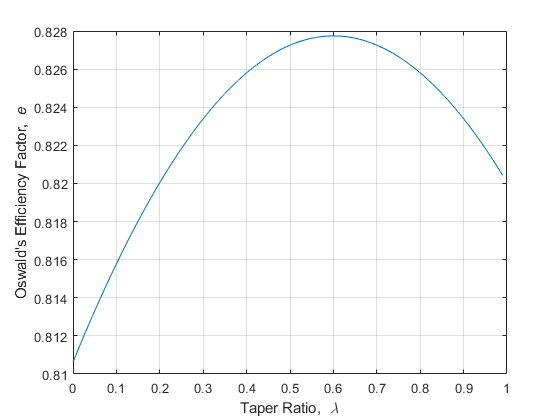


plot (TaperRatio,e)
xlabel('Taper Ratio, {\it \lambda}')
ylabel("Oswald's Efficiency Factor, {\it e}")
grid on